F = 1;
M = 1;
b = 10;
k = 20;

%%P Controller
%Kp= 500; %1000, 200, 800
%Ki =0;
%Kd = 0;
%sim('PID_MassSDModel')

%%PID Controller
Kp = 400;
Ki = 900;
Kd = 40;
sim('TunePID')

ans =   Simulink.SimulationOutput:

                     IN: [1x1 timeseries] 
                    OUT: [1x1 timeseries] 
                   tout: [200x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


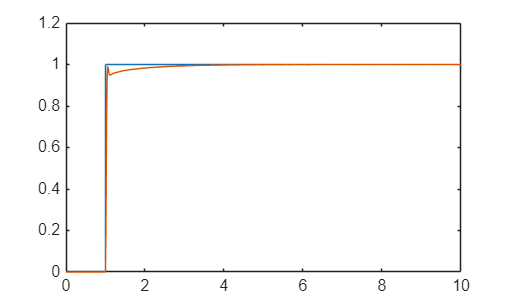

%%Plot
figure
plot(out.IN.time, out.IN.data)
hold all
plot(out.OUT.time, out.OUT.data)